function noise=noise_generator(rows,columns,noise_mean,noise_sd)
    mean=noise_mean;
    sd=noise_sd;
    noise=zeros(columns,rows);
    for i=1:columns
        n=mean+sd*rand(1,rows);
        noise(i,:)=n;
    end
    noise=noise';
end

function scans=scans_generator(image,times,angles,noise_mean,noise_sd)
    R=radon(image,angles);
    [rows,columns]=size(R);
    scans=zeros(times,rows,columns);

    for i=1:times
        noise=noise_generator(rows,columns,noise_mean,noise_sd);
        R_with_n=R+noise;
        scans(i,:,:)=R_with_n;
    end
end

function [Iterative_recon,back_recon,MSE_iter,MSE_back,scans]=iter_workflow(ground_truth,assumed_image,times,angles,noise_mean,noise_sd)
    
    [l,w]=size(ground_truth);

    R_assumed=radon(assumed_image,angles);
    scans=scans_generator(ground_truth,times,angles,noise_mean,noise_sd);
    for i=1:times
        result=squeeze(scans(i,:,:))-R_assumed;
        R_assumed=R_assumed+result/times;
    end
    Iterative_recon=iradon(R_assumed,angles,"linear","Shepp-Logan",l);
    first_noise=squeeze(scans(1,:,:));
    back_recon=iradon(first_noise,angles,"linear","Shepp-Logan",l);
    Iterative_recon_norm=normalizer(Iterative_recon);
    back_recon_norm=normalizer(back_recon);

    temp=(Iterative_recon_norm-ground_truth).^2;
    MSE_iter=sum(temp(:))/(l*w);
    temp=(back_recon_norm-ground_truth).^2;
    MSE_back=sum(temp(:))/(l*w);
end

function recon_norm=normalizer(recon)
    recon_norm=(recon-min(recon(:)))/(max(recon(:))-min(recon(:)));
end

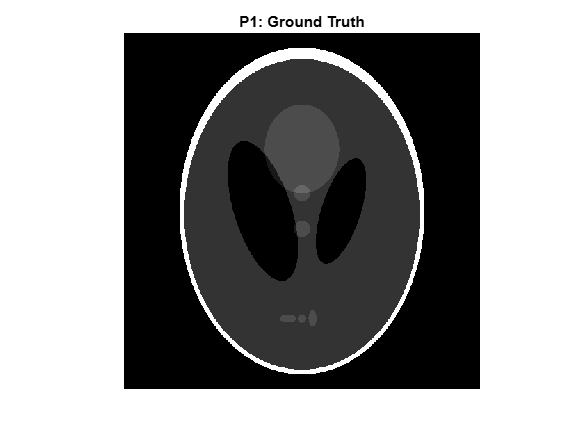

% P1: Introduction
P=phantom("Modified Shepp-Logan",512);
angles=0:0.2:179.8;
figure;
imshow(P);
title("P1: Ground Truth");

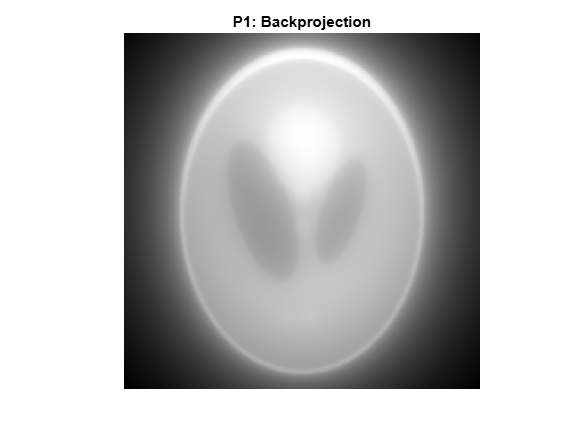


R=radon(P,angles);
figure;
reconed=iradon(R,angles,"linear","None",512);
figure;
imshow(reconed,[]);
title("P1: Backprojection");

[rows,columns]=size(R);

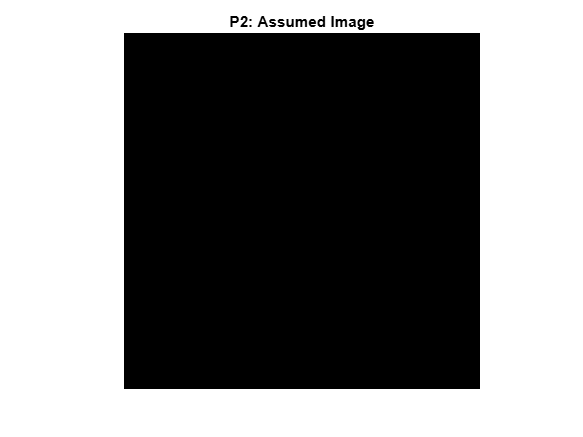

% P2: Iteration
% Start with a black image
assumed_black=zeros(512,512);
figure;
imshow(assumed_black);
title("P2: Assumed Image");

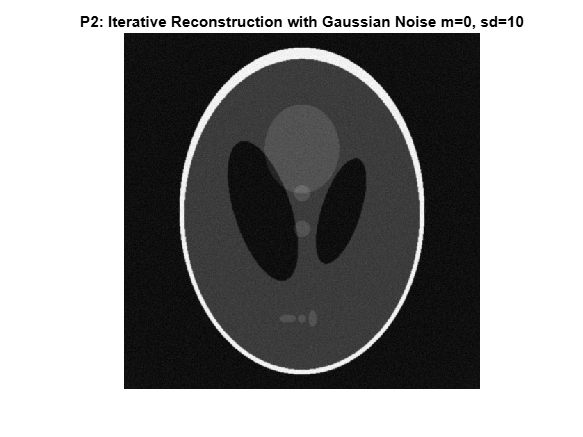


% Scan 10 times at a slice, and adding Gaussian noise to simulate real circumstances.

[Iterative_recon_10_10_black_P2,back_recon_10_black_P2,MSE_iter_10_10_black_P2,MSE_back_10_black_P2,scans_10_10_black_P2]=iter_workflow(P,assumed_black,10,angles,0,10);
figure;
imshow(Iterative_recon_10_10_black_P2,[]);
title("P2: Iterative Reconstruction with Gaussian Noise m=0, sd=10");

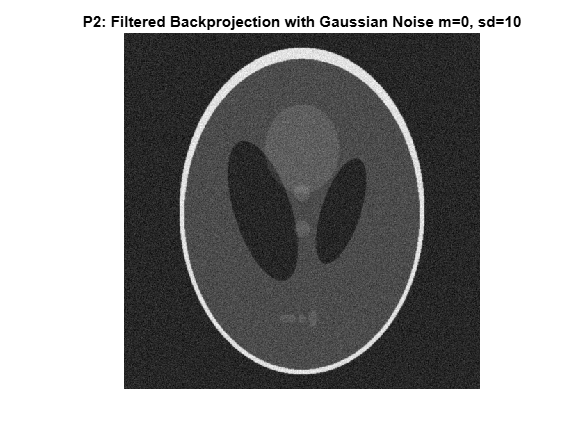

figure;
imshow(back_recon_10_black_P2,[]);
title("P2: Filtered Backprojection with Gaussian Noise m=0, sd=10");


% Here I use MSE to evaluate the imaging quality.
disp("The MSE of iterative reconstruction is "+num2str(MSE_iter_10_10_black_P2));

The MSE of iterative reconstruction is 0.0040099


disp("The MSE of filtered backprojection is "+num2str(MSE_back_10_black_P2));

The MSE of filtered backprojection is 0.019856


The image of iterative reconstruction is significantly better than backprojection when noises are presented; the MSE is smaller, too.

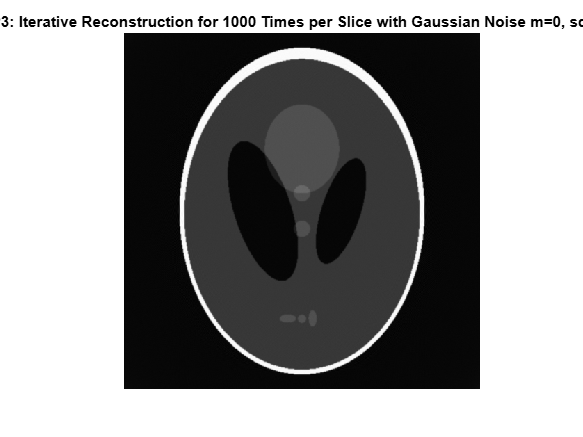

% P3: The influence of iteration times.

[Iterative_recon_10_1000_black_P3,back_recon_10_black_P3,MSE_iter_10_1000_black_P3,MSE_back_10_black_P3,scans_10_1000_black_P3]=iter_workflow(P,assumed_black,1000,angles,0,10);

figure;
imshow(Iterative_recon_10_1000_black_P3,[]);
title("P3: Iterative Reconstruction for 1000 Times per Slice with Gaussian Noise m=0, sd=10");

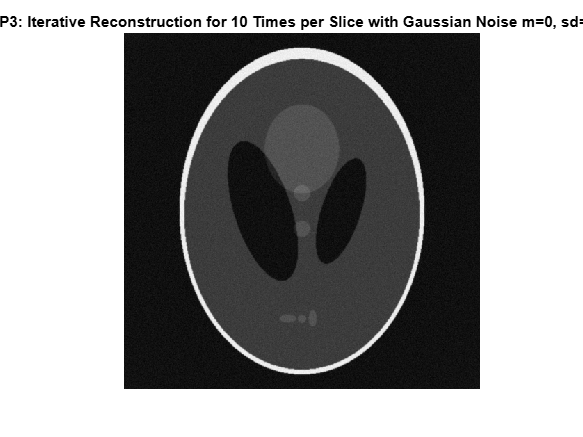


R_assumed_10_10_black_P3=radon(assumed_black,angles);
for i=1:10
    result=squeeze(scans_10_1000_black_P3(i,:,:))-R_assumed_10_10_black_P3;
    R_assumed_10_10_black_P3=R_assumed_10_10_black_P3+result/10;
end

iter_10_10_black_P3=iradon(R_assumed_10_10_black_P3,angles,"linear","Shepp-Logan",512);
figure;
imshow(iter_10_10_black_P3,[]);
title("P3: Iterative Reconstruction for 10 Times per Slice with Gaussian Noise m=0, sd=10");

MSE_iter_10_10_black_P3=(iter_10_10_black_P3-P).^2;
MSE_iter_10_10_black_P3=sum(MSE_iter_10_10_black_P3(:))/(512*512);
disp("The MSE of iterative reconstruction for 1000 times is "+num2str(MSE_iter_10_1000_black_P3));

The MSE of iterative reconstruction for 1000 times is 0.0016509


disp("The MSE of iterative reconstruction for 10 times is "+num2str(MSE_iter_10_10_black_P3));

The MSE of iterative reconstruction for 10 times is 0.0086172


Adding iterative frequency can improve the image quality.

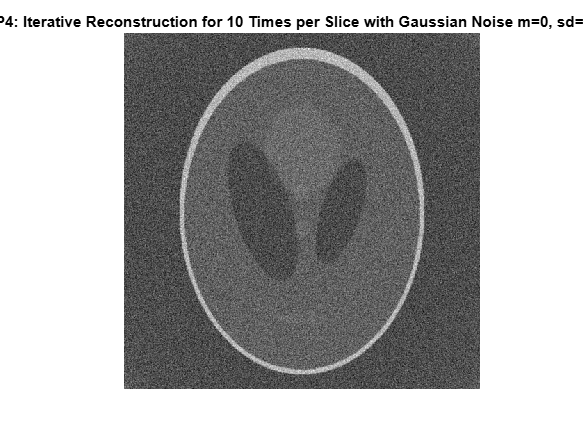

% P4: The influence of noise.

[Iterative_recon_100_1000_black_P4,back_recon_100_black_P4,MSE_iter_100_1000_black_P4,MSE_back_100_black_P4,scans_100_1000_black_P4]=iter_workflow(P,assumed_black,1000,angles,0,100);

R_assumed_100_1000_black_P4=radon(assumed_black,angles);
for i=1:10
    result=squeeze(scans_100_1000_black_P4(i,:,:))-R_assumed_100_1000_black_P4;
    R_assumed_100_1000_black_P4=R_assumed_100_1000_black_P4+result/10;
end
Iterative_recon_100_10_black_P4=iradon(R_assumed_100_1000_black_P4,angles,"linear","Shepp-Logan",512);
figure;
imshow(Iterative_recon_100_10_black_P4,[]);
title("P4: Iterative Reconstruction for 10 Times per Slice with Gaussian Noise m=0, sd=100")

MSE_iter_100_10_black_P4=(Iterative_recon_100_10_black_P4-P).^2;
MSE_iter_100_10_black_P4=sum(MSE_iter_100_10_black_P4(:))/(512*512);
disp("The MSE of iterative reconstruction for 10 times per slice with noise m=0, sd=100 is "+num2str(MSE_iter_100_10_black_P4));

The MSE of iterative reconstruction for 10 times per slice with noise m=0, sd=100 is 0.018168


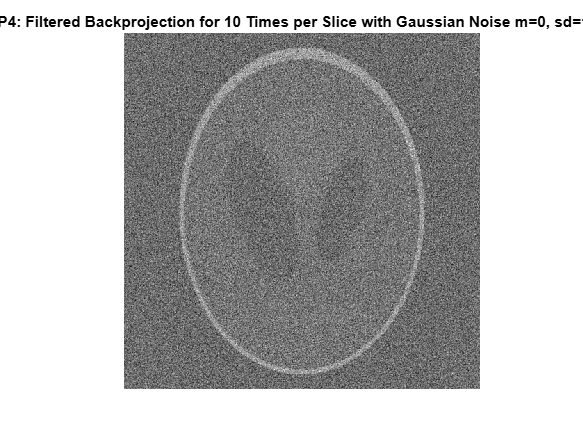


imshow(back_recon_100_black_P4,[]);
title("P4: Filtered Backprojection for 10 Times per Slice with Gaussian Noise m=0, sd=100");

disp("The MSE of filtered backprojection for 10 times per slice with noise m=0, sd=100 is "+num2str(MSE_back_100_black_P4));

The MSE of filtered backprojection for 10 times per slice with noise m=0, sd=100 is 0.14239


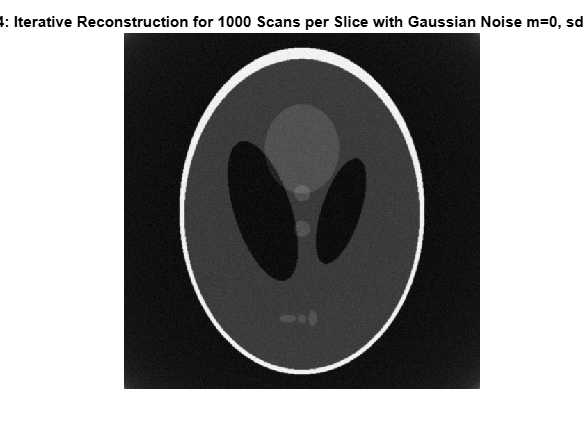


% Adding iteration frequency to 1000.

figure;
imshow(Iterative_recon_100_1000_black_P4,[]);
title("P4: Iterative Reconstruction for 1000 Scans per Slice with Gaussian Noise m=0, sd=100");

disp("The MSE of iterative reconstruction for 1000 scans per slice with noise m=0, sd=100 is "+num2str(MSE_iter_100_1000_black_P4));

The MSE of iterative reconstruction for 1000 scans per slice with noise m=0, sd=100 is 0.0047425


More noisy signals can have an improved recon by adding iteration frequency. It seems like the iteration frequency have to go N^2 to get the similar quality when the standard deviation of the noise goes to N times more.

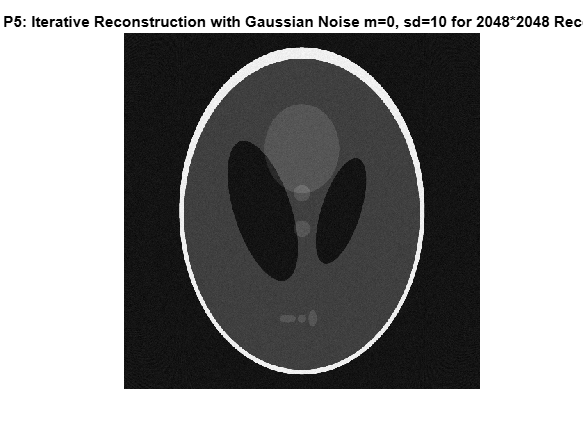

% P5: The influence of the size of recon.

ground_truth_2048=phantom("Modified Shepp-Logan",2048);
assumed_2048=zeros(2048,2048);

[Iterative_recon_10_10_black_2048_P5,back_recon_10_black_2048_P5,MSE_iter_10_10_black_2048_P5,MSE_back_10_black_2048_P5,scans_10_10_black_2048_P5]=iter_workflow(ground_truth_2048,assumed_2048,10,angles,0,10);
figure;
imshow(Iterative_recon_10_10_black_2048_P5,[]);
title("P5: Iterative Reconstruction with Gaussian Noise m=0, sd=10 for 2048*2048 Recon");

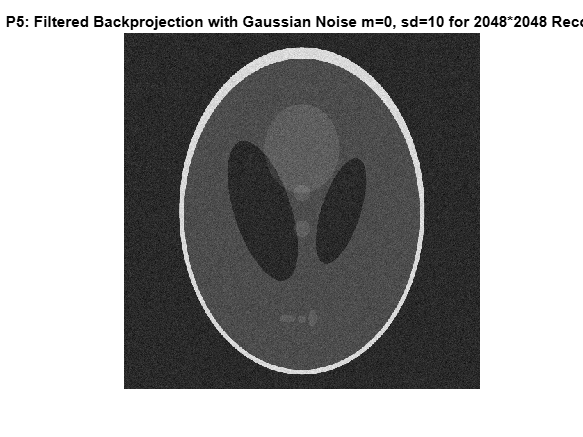

figure;
imshow(back_recon_10_black_2048_P5,[]);
title("P5: Filtered Backprojection with Gaussian Noise m=0, sd=10 for 2048*2048 Recon");


disp("The MSE of iterative reconstruction is "+num2str(MSE_iter_10_10_black_2048_P5));

The MSE of iterative reconstruction is 0.0050107


disp("The MSE of filtered backprojection is "+num2str(MSE_back_10_black_2048_P5));

The MSE of filtered backprojection is 0.021542


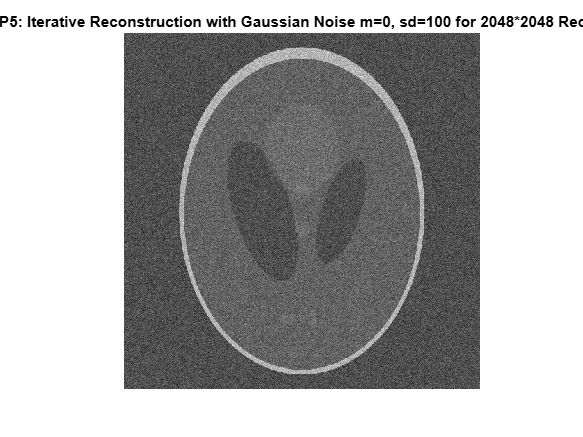


[Iterative_recon_100_10_black_2048_P5,back_recon_100_black_2048_P5,MSE_iter_100_10_black_2048_P5,MSE_back_100_black_2048_P5,scans_100_10_black_2048_P5]=iter_workflow(ground_truth_2048,assumed_2048,10,angles,0,100);
figure;
imshow(Iterative_recon_100_10_black_2048_P5,[]);
title("P5: Iterative Reconstruction with Gaussian Noise m=0, sd=100 for 2048*2048 Recon");

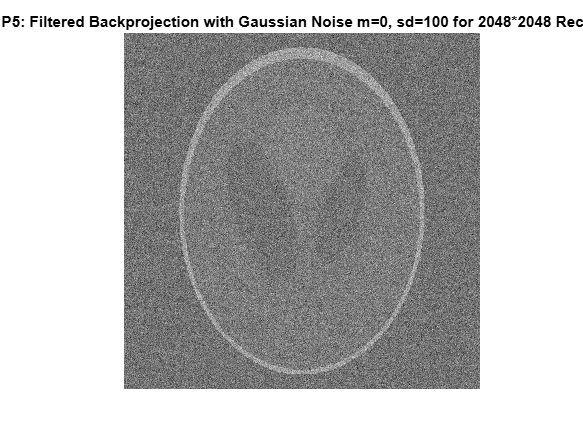

figure;
imshow(back_recon_100_black_2048_P5,[]);
title("P5: Filtered Backprojection with Gaussian Noise m=0, sd=100 for 2048*2048 Recon");


disp("The MSE of iterative reconstruction is "+num2str(MSE_iter_100_10_black_2048_P5));

The MSE of iterative reconstruction is 0.075182


disp("The MSE of filtered backprojection is "+num2str(MSE_back_100_black_2048_P5));

The MSE of filtered backprojection is 0.16099


The size of reconstruction does not seem to have an effect on image quality.

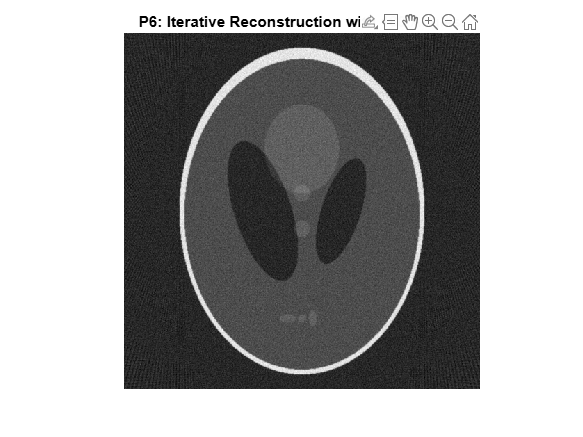

% P6: The influence of angles.
angles_180=0:1:179.8;
[Iterative_recon_10_10_black_180angles_P6,back_recon_10_black_180angles_P6,MSE_iter_10_10_black_180angles_P6,MSE_back_10_black_180angles_P6,scans_P6_10_10_black_180angles_P6]=iter_workflow(P,assumed_black,10,angles_180,0,10);
figure;
imshow(Iterative_recon_10_10_black_180angles_P6,[]);
title("P6: Iterative Reconstruction with 180 Angles.");

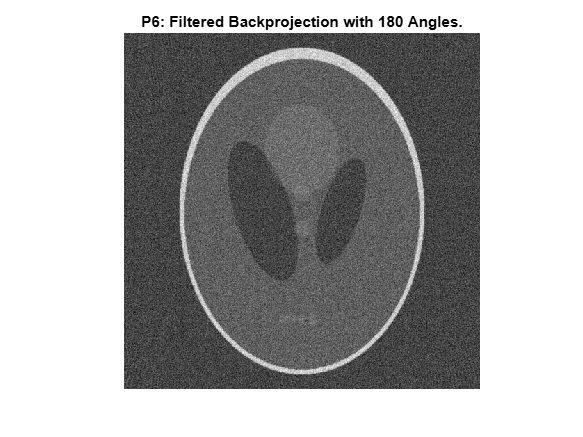

figure;
imshow(back_recon_10_black_180angles_P6,[]);
title("P6: Filtered Backprojection with 180 Angles.");


disp("The MSE of iterative reconstruction is "+num2str(MSE_iter_10_10_black_180angles_P6));

The MSE of iterative reconstruction is 0.02003


disp("The MSE of filtered backprojection is "+num2str(MSE_back_10_black_180angles_P6));

The MSE of filtered backprojection is 0.058739


The image quality of a less-angle reconstruction follows the rules so far.

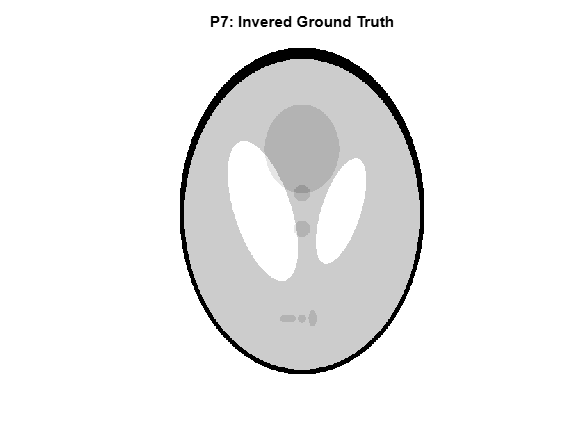

% P7: The influence of assumed image. Further could show the speed of reconstruction.

% Assuming the inverse of the ground truth.

inversed_ground_truth=ones(512,512);
inversed_ground_truth=inversed_ground_truth-P;
figure;
imshow(inversed_ground_truth);
title("P7: Invered Ground Truth");

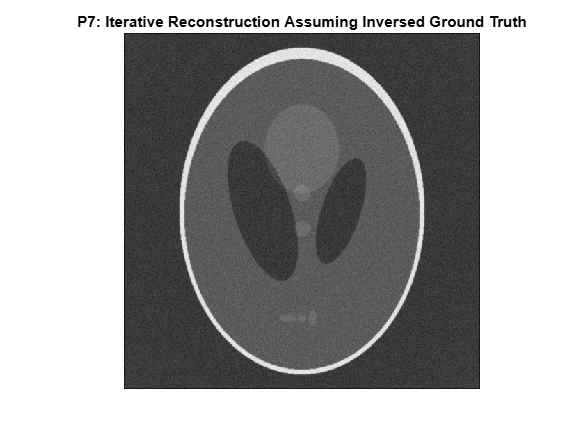


[Iterative_recon_10_10_inverse_P7,back_recon_10_inverse_P7,MSE_iter_10_10_inverse_P7,MSE_back_10_inverse_P7,scans_10_10_inverse_P7]=iter_workflow(P,inversed_ground_truth,10,angles,0,10);
figure;
imshow(Iterative_recon_10_10_inverse_P7,[]);
title("P7: Iterative Reconstruction Assuming Inversed Ground Truth");


disp("The MSE of iterative reconstruction is "+num2str(MSE_iter_10_10_inverse_P7));

The MSE of iterative reconstruction is 0.040808


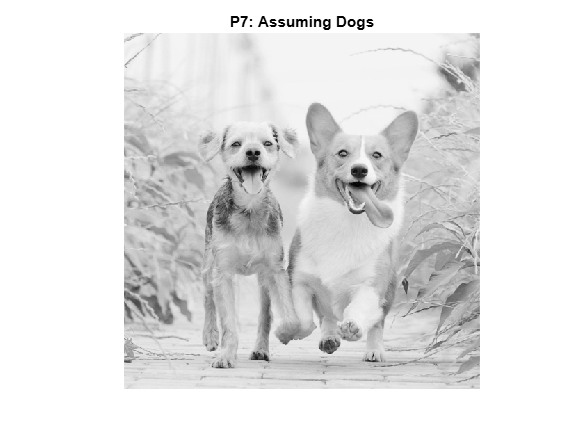


% Assuming two dogs.

dogs=imread("dogs.jpg");
dogs=imresize(dogs,[512,512]);
dogs=rgb2gray(dogs);
imshow(dogs);
title("P7: Assuming Dogs");

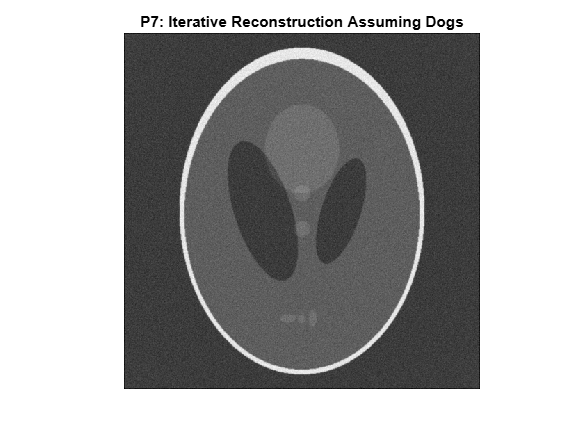


[Iterative_recon_10_10_dogs_P7,back_recon_10_dogs_P7,MSE_iter_10_10_dogs_P7,MSE_back_10_dogs_P7,scans_10_10_dogs_P7]=iter_workflow(P,inversed_ground_truth,10,angles,0,10);
figure;
imshow(Iterative_recon_10_10_dogs_P7,[]);
title("P7: Iterative Reconstruction Assuming Dogs");


disp("The MSE of iterative reconstruction is "+num2str(MSE_iter_10_10_dogs_P7));

The MSE of iterative reconstruction is 0.044229


The assumed image affects the final imaging.

However, it is a quite simple implementation. In real situation, the noise acquired by each scan has different invariances. We could have weighted updates based on the noise invariances. It is necessary for us to have a good estimate.

If we used gradient-descending for updates, then the assumed image matters more: the convergence time and quality depends on it. 

Conclusion so far:

Iterative recon would be better than filtered backprojection under same condition. 

Iterative recon with higher frequency would be better under same condition.

Reconstruction size would not affect the quality of iterative recon under same condition.

Different assumptions about the actual image would result in different reconstruction quality.

What's next:

- prove/disprove the relationship of the needed frequency under noise SD=nb in order to get similar quality when reconstruct under noise SD=b.

- Investigate better choise for initial assumption, and the eventuality of image quality convergence.

% P8 The relationship of the needed frequency under noise SD=nb in order to get similar quality when reconstruct under noise SD=b

% Assume black

[Iterative_recon_10_10_black_P8,back_recon_10_black_P8,MSE_iter_10_10_black_P8,MSE_back_10_black_P8,scans_10_10_black_P8]=iter_workflow(P,assumed_black,10,angles,0,10);
[Iterative_recon_20_40_black_P8,back_recon_40_black_P8,MSE_iter_20_40_black_P8,MSE_back_40_black_P8,scans_20_40_black_P8]=iter_workflow(P,assumed_black,40,angles,0,20);
[Iterative_recon_40_160_black_P8,back_recon_160_black_P8,MSE_iter_40_160_black_P8,MSE_back_160_black_P8,scans_40_160_black_P8]=iter_workflow(P,assumed_black,160,angles,0,40);
[Iterative_recon_80_640_black_P8,back_recon_640_black_P8,MSE_iter_80_640_black_P8,MSE_back_640_black_P8,scans_80_640_black_P8]=iter_workflow(P,assumed_black,640,angles,0,80);
[Iterative_recon_80_200_black_P8,back_recon_200_black_P8,MSE_iter_80_200_black_P8,MSE_back_200_black_P8,scans_80_200_black_P8]=iter_workflow(P,assumed_black,200,angles,0,80);




ratio for SD=20 and SD=10: 0.97296


disp("ratio for SD=20 and SD=10: "+num2str(MSE_iter_20_40_black_P8/MSE_iter_10_10_black_P8));

ratio for SD=40 and SD=10: 0.94543


disp("ratio for SD=40 and SD=10: "+num2str(MSE_iter_40_160_black_P8/MSE_iter_10_10_black_P8));

ratio for SD=80 and SD=10: 1.0589


disp("ratio for SD=80 and SD=10: "+num2str(MSE_iter_80_640_black_P8/MSE_iter_10_10_black_P8));

ratio withfor SD=80 and SD=10: 2.1428


disp("ratio withfor SD=80 and SD=10: "+num2str(MSE_iter_80_200_black_P8/MSE_iter_10_10_black_P8));

The ratios are around 1. The relationship is proved to be right in my cases. 

% P9 Initial assumptions

assumpt_ground_truth=P;
assumpt_white=ones(512,512);
[Iterative_recon_50_10_black_P9,back_recon_50_black_P9,MSE_iter_50_10_black_P9,MSE_back_50_black_P9,scans_50_10_black_P9]=iter_workflow(P,assumed_black,10,angles,0,50);
[Iterative_recon_50_10_white_P9,back_recon_50_white_P9,MSE_iter_50_10_white_P9,MSE_back_50_white_P9,scans_50_10_white_P9]=iter_workflow(P,assumpt_white,10,angles,0,50);
[Iterative_recon_50_10_dogs_P8,back_recon_50_dogs_P9,MSE_iter_50_10_dogs_P9,MSE_back_50_dogs_P9,scans_50_10_dogs_P9]=iter_workflow(P,dogs,10,angles,0,50);
[Iterative_recon_50_10_inversed_P8,back_recon_50_inversed_P9,MSE_iter_50_10_inversed_P9,MSE_back_50_inversed_P9,scans_50_10_inversed_P9]=iter_workflow(P,inversed_ground_truth,10,angles,0,50);
[Iterative_recon_50_10_ground_truth_P9,back_recon_50_ground_truth_P9,MSE_iter_50_10_ground_truth_P9,MSE_back_50_ground_truth_P9,scans_50_10_ground_truth_P9]=iter_workflow(P,assumpt_ground_truth,10,angles,0,50);


MSE when assume black: 0.042048


disp("MSE when assume black: "+num2str(MSE_iter_50_10_black_P9));

MSE when assume white: 0.043525


disp("MSE when assume white: "+num2str(MSE_iter_50_10_white_P9));

MSE when assume dogs: 0.52325


disp("MSE when assume dogs: "+num2str(MSE_iter_50_10_dogs_P9));

MSE when assume inversed: 0.10021


disp("MSE when assume inversed: "+num2str(MSE_iter_50_10_inversed_P9));

MSE when assume ground truth: 0.025159


disp("MSE when assume ground truth: "+num2str(MSE_iter_50_10_ground_truth_P9));

But in reality we could not know the ground truth. This time we use a filtered backprojection as the assumption.

assumpt_filtered_backprojection=back_recon_50_black_P9;
[Iterative_recon_50_10_filtered_backprojection_P9,back_recon_50_filtered_backprojection_P9,MSE_iter_50_10_filtered_backprojection_P9,MSE_back_50_filtered_backprojection_P9,scans_50_10_filtered_backprojection_P9]=iter_workflow(P,assumpt_filtered_backprojection,10,angles,0,50);

MSE when assume based on a filtered backprojection: 0.031966


disp("MSE when assume based on a filtered backprojection: "+num2str(MSE_iter_50_10_filtered_backprojection_P9));

Evidently, using filtered backprojection as assumption is better for iterative recon. It could help shortening iteration time and get better quality.

Does each assumption converges to a certain quality?

[Iterative_recon_50_1000_dogs_P8,back_recon_50_dogs_P9,MSE_iter_50_1000_dogs_P9,MSE_back_50_dogs_P9,scans_50_1000_dogs_P9]=iter_workflow(P,dogs,1000,angles,0,50);

MSE when assume dogs with f=1000: 0.52356


disp("MSE when assume dogs with f=1000: "+num2str(MSE_iter_50_1000_dogs_P9));

Iterative recon seems to have the same problem as machine learning: not all start points would be able to reach global minimum. In this case, when assumption is dogs, the image quality would not improve even with large frequencies.

I revisited statistics courses I took in college, and proved the relationship mentioned in P8.

Let **θ** be the real situation, and let **θ_hat** be estimation. θ_hat=θ+η, where η~N[0,a^2].

MSE=E[(θ_hat - θ)^2]

=E[ ( θ_hat-E[θ_hat] + E[θ_hat]-θ )^2 ]

Now, 

( θ_hat-E[θ_hat] + E[θ_hat]-θ )^2 = (θ_hat-E[θ_hat])^2 + 2*(θ_hat-E[θ_hat])*(E[θ_hat]-θ) +(E[θ_hat]-θ)^2.

Then,

MSE= E[(θ_hat-E[θ_hat])^2] + 2*E[(θ_hat-E[θ_hat])*(E[θ_hat]-θ)] + E[(E[θ_hat]-θ)^2].

Since E[(θ_hat-E[θ_hat])=0, MSE=E[(E[θ_hat]-θ)^2]=variance. So the MSE~variance of the noise=(standard deviation of the noise)^2.

QED